# 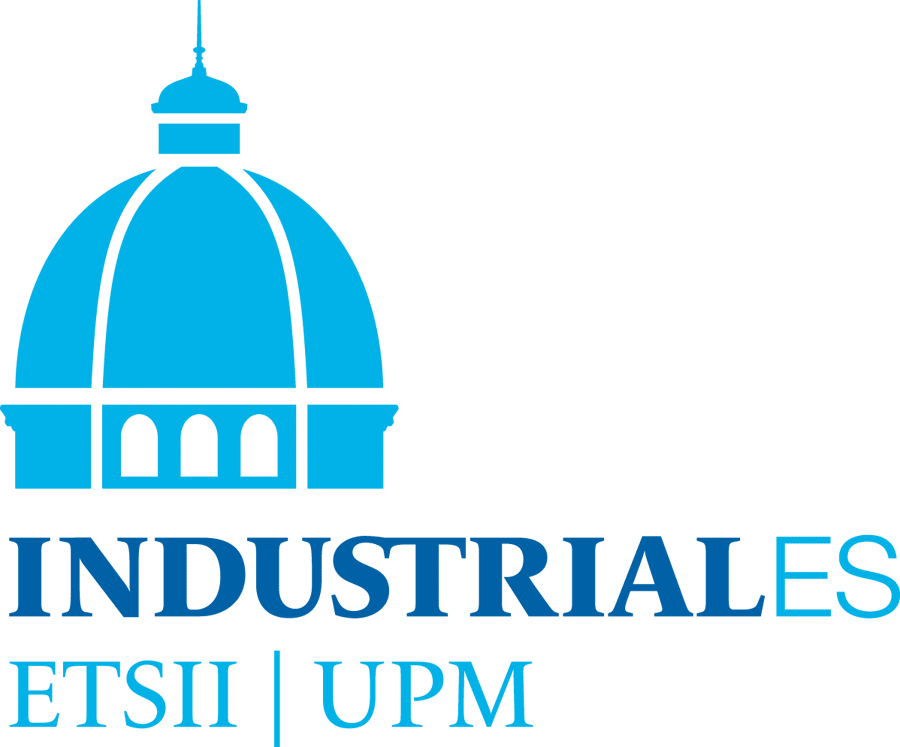 [ETSII](http://www.etsii.upm.es)    [MathWorks](http://www.mathworks.com)

# **FUNDAMENTOS de AUTOMÁTICA**

**PRÁCTICA 1 - Curso 2020/2021 **

**Enrique Pinto (enrique.pinto@upm.es)**

# **Análisis con el lugar de las raíces**

## Sistema REAL

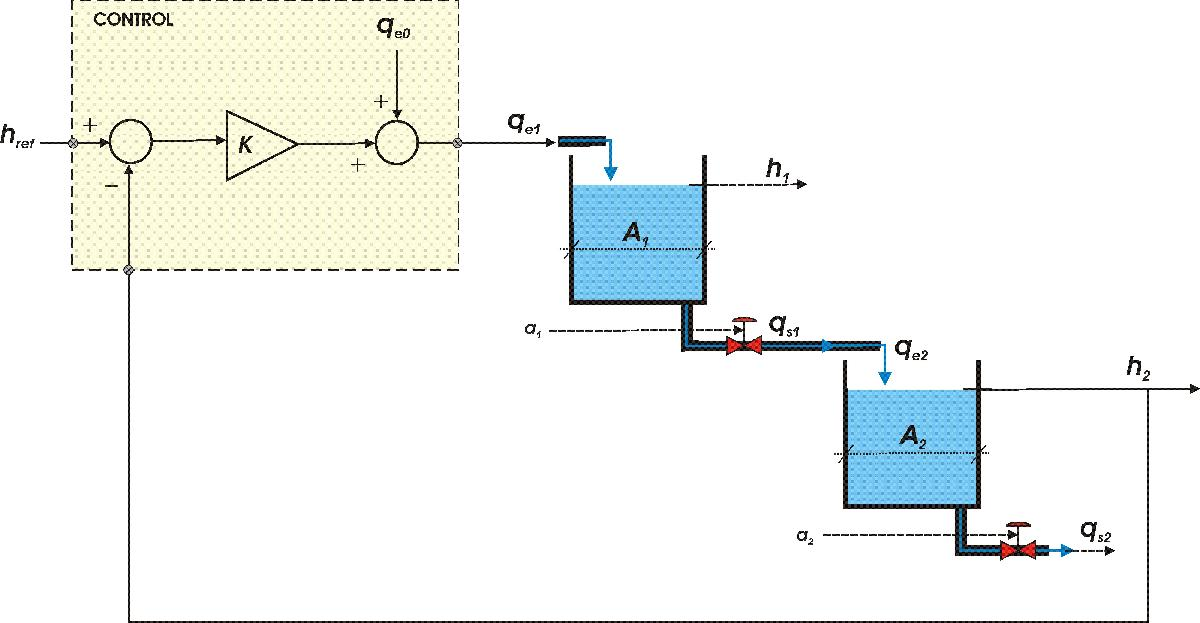

                                                                                        **Depósito 1:  A1= 2.6 m^2,  a1= 0.1           Depósito 2:  A1= 1.7 m^2,   a2= 0.1**

## Modelo LINEAL (obtenido en Dinámica de Sistemas)

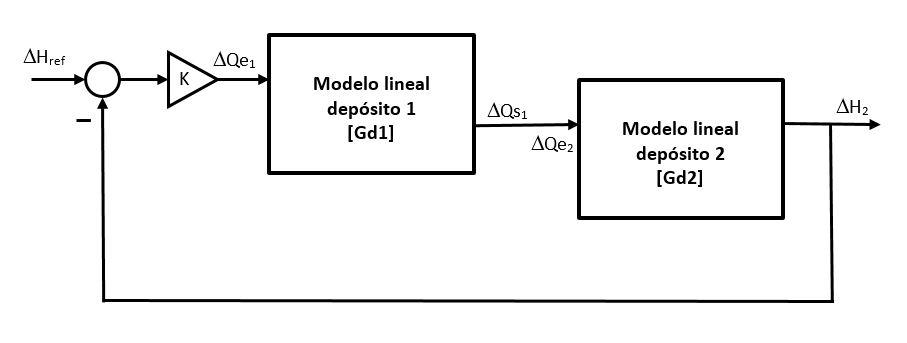

                                  K=1         $\textrm{Gd1}=\frac{\Delta {\textrm{Qs}}_1 }{\Delta {\textrm{Qe}}_1 }=\frac{0\ldotp 03141}{s+0\ldotp 03141}$                $\textrm{Gd2}=\frac{\Delta H_2 }{\Delta {\textrm{Qe}}_2 }=\frac{0\ldotp 5882}{s+0\ldotp 04804}$

Declaración con [tf](https://es.mathworks.com/help/control/ref/tf.html)  (*Gd1*)        $G\left(s\right)=\frac{b_m {\;s}^m +\cdots +b_1 s+b_0 }{a_n {\;s}^n +\cdots +a_1 s+a_0 }$   $n\ge m$ para físicamente realizable

Gd1=tf(0.03141,[1 0.03141]) % Gd1=▲Qs1/▲Qe1 argumentos: coeficientes de los polinomios en 's'


Gd1 =
 
    0.03141
  -----------
  s + 0.03141
 
Continuous-time transfer function.



Gd2=tf(0.5882,[1 0.04804])  % Gd2=▲H2/▲Qe2 argumentos: idem


Gd2 =
 
    0.5882
  -----------
  s + 0.04804
 
Continuous-time transfer function.



K=1;    % declaración de ganancia K

Función de transferencia en bucle abierto  (*Gba*) 

Gba=Gd1*Gd2  % Gba=▲H2/▲Qe1


Gba =
 
           0.01848
  --------------------------
  s^2 + 0.07945 s + 0.001509
 
Continuous-time transfer function.



**RECUERDA:** también se puede ejecutar [series](https://es.mathworks.com/help/control/ref/series.html) $\to$ Gba=*series*(Gd1,Gd2)

Cambio a formato con [zpk](https://es.mathworks.com/help/control/ref/zpk.html) (*Gba*)      $G\left(s\right)=K\frac{\prod_{i=1}^m \left(s-z_i \right)}{\prod_{i=1}^n \left(s-p_i \right)}$   ceros (*z*), polos (*p*), ganancia *(K*)

Gba=zpk(Gba)  % tf -> zpk


Gba =
 
         0.018475
  -----------------------
  (s+0.04804) (s+0.03141)
 
Continuous-time zero/pole/gain model.



Asignación de nombres

set(Gba,'InputName','Qe')   % Qe señal de entrada
set(Gba,'OutputName','H2')  % H2 señal de salida
Gba      % mostrar Gba


Gba =
 
  From input "Qe" to output "H2":
         0.018475
  -----------------------
  (s+0.04804) (s+0.03141)
 
Continuous-time zero/pole/gain model.



## Lugar de las raíces 

Directo: lugar geométrico de $p\left(s\right)=1+K\;G\left(s\right)H\left(s\right)=0$   con K>0

Inverso: lugar geométrico de $p\left(s\right)=1+K\;G\left(s\right)H\left(s\right)=0$   con K<0

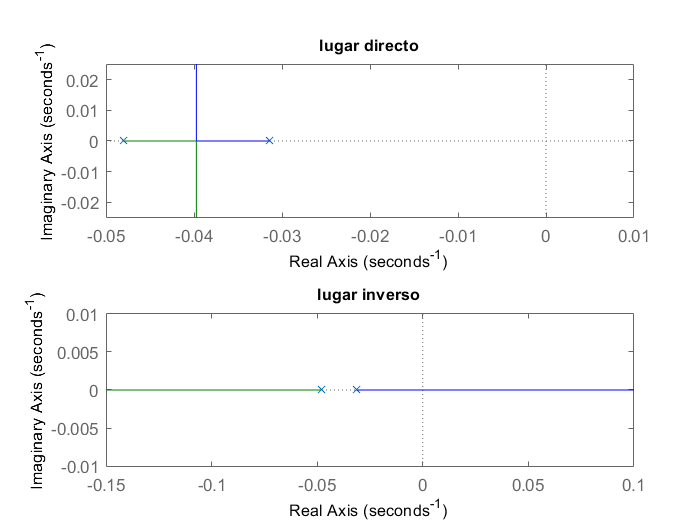

 figure  % nueva figura
subplot(2,1,1)  % dividir plot en 2 zonas, activando zona 1
 rlocus(Gba) % obtención del lugar directo variaciones de K positivas
title('lugar directo')  % insertar título 

subplot(2,1,2)  % dividir plot en 2 zonas, activando zona 2
 rlocus(-Gba) % obtención del lugar inverso variaciones de K negativas
 title('lugar inverso') % insertar título 

**CONCLUSIÓN:** el sistema realimentado es estable ante cualquier variación de K>0 y lo comprobamos a continuación:

Obtención del valor crítico de K con [margin](https://es.mathworks.com/help/control/ref/margin.html)  (*Kcritica*)

Valor de K que inestabiliza la respuesta del sistema

 kcritica=margin(Gba) % margen de estabilidad

kcritica = Inf

## Modelo LINEAL con retardo (obtenido en Dinámica de Sistemas)

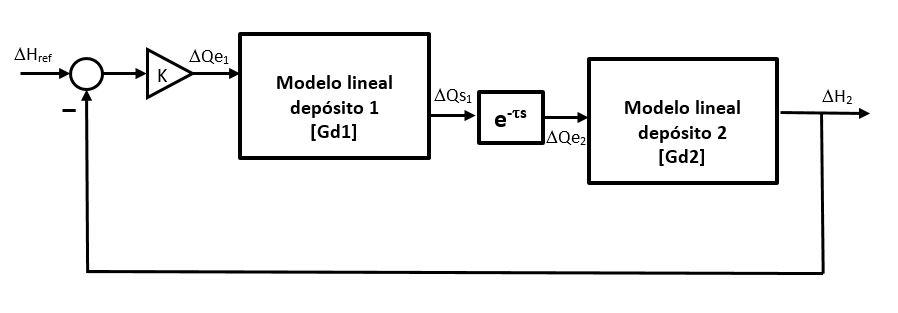

**                                Retardo de 2.5" en el caudal que circula entre los depósitos**

Nueva función de transferencia en bucle abierto  (*Gba_ret_aprox*)

retardo=tf(1,1,'IODelay',2.5)  % declaración bloque retardo con Tau=2.5"


retardo =
 
  exp(-2.5*s) * (1)
 
Continuous-time transfer function.



 Gba_ret=Gba*retardo % función en bucle abierto con retardo


Gba_ret =
 
  From input to output "H2":
                       0.018475
  exp(-2.5*s) * -----------------------
                (s+0.04804) (s+0.03141)
 
Continuous-time zero/pole/gain model.



 Gba_ret_aprox=pade(Gba_ret,1) % aproximación de Padé con un término


Gba_ret_aprox =
 
  From input to output "H2":
         -0.018475 (s-0.8)
  -------------------------------
  (s+0.04804) (s+0.03141) (s+0.8)
 
Continuous-time zero/pole/gain model.



**RECUERDA:** usamos [pade](https://es.mathworks.com/help/control/ref/pade.html) para expresar la función de transferencia como cociente de zeros/polos 

                                                             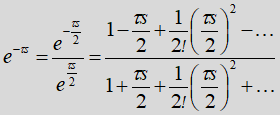

Nuevo lugar de las raíces

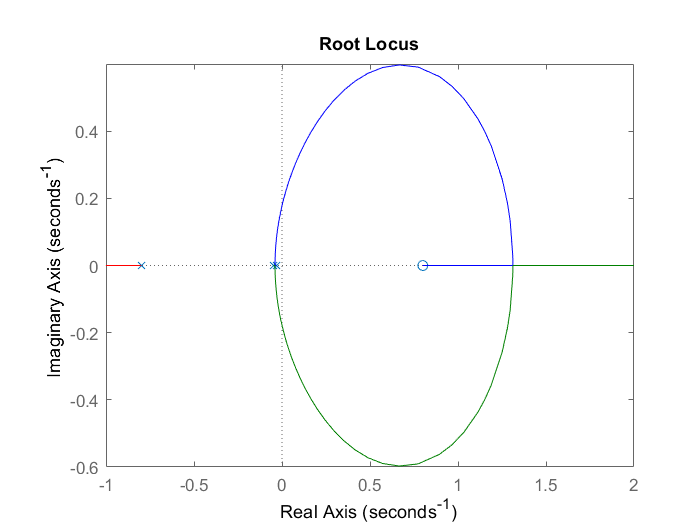

figure  % nueva figura
 rlocus(Gba_ret_aprox) % lugar directo
 axis([-1 2 -0.6 0.6]) % escalado de ejes de -1 a 2 en X, de -0.6 a 0.6 en Y

**CONCLUSIÓN:** el sistema realimentado será inestable para un determinado valor de K>0 y lo comprobamos a continuación:

Obtención del valor crítico de K con [margin](https://es.mathworks.com/help/control/ref/margin.html)  (*Kcritica_ret*)

Valor de K que inestabiliza la respuesta del sistema

Kcritica_ret=margin(Gba_ret_aprox)  % margen de estabilidad

Kcritica_ret = 1.8053

## **Análisis del sistema realimentado con retardo**

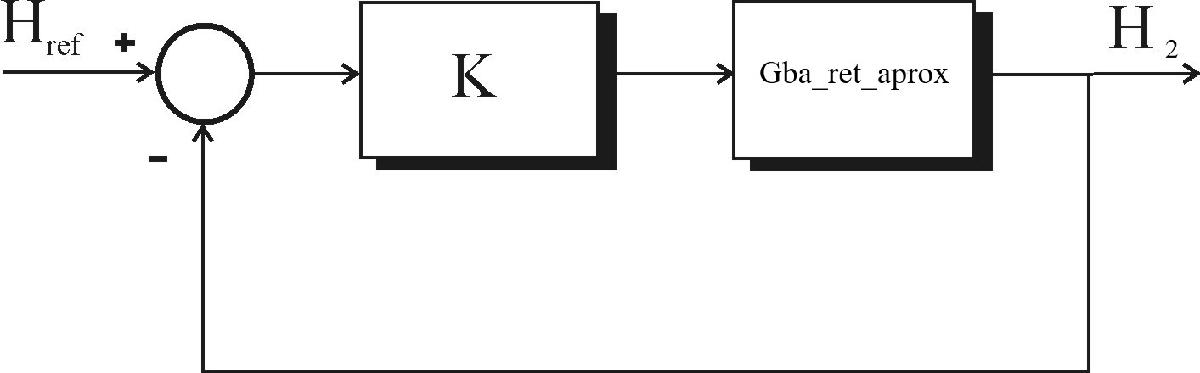

Con K=1   (*Gbc_ret*)    

K=1;  % valor de K
 Gbc_ret=feedback(K*Gba_ret_aprox,1) % función de transferencia en bucle cerrado


Gbc_ret =
 
            -0.018475 (s-0.8)
  -------------------------------------
  (s+0.8467) (s^2 + 0.03273s + 0.01888)
 
Continuous-time zero/pole/gain model.




set(Gbc_ret,'InputName','Href') % Href señal de entrada
set(Gbc_ret,'OutputName','H2')  % H2 señal de salida
Gbc_ret    % mostrar Gbc_ret


Gbc_ret =
 
  From input "Href" to output "H2":
            -0.018475 (s-0.8)
  -------------------------------------
  (s+0.8467) (s^2 + 0.03273s + 0.01888)
 
Continuous-time zero/pole/gain model.



Polos del sistema realimentado (*polos_bc*)

 polos_bc=pole(Gbc_ret) % polos del sistema en bucle cerrado

polos_bc =   -0.8467 + 0.0000i
  -0.0164 + 0.1364i
  -0.0164 - 0.1364i


Superposición de los polos sobre el lugar directo

rlocus(Gba_ret_aprox)  % lugar directo
hold  % mantener resultado gráfico anterior

Current plot held


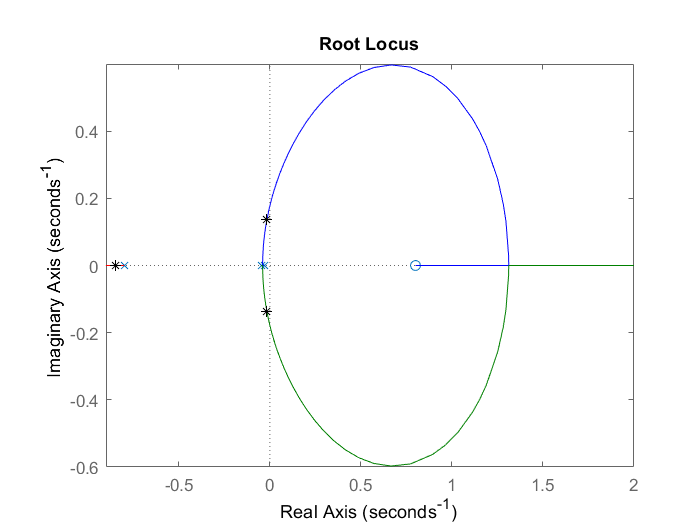

plot(-0.8467,0,'k*')  % añadir el polo real, en negro y con asterisco ('k*')
plot(-0.0164,0.1364,'k*')  % añadir el polo complejo con parte imaginaria +
plot(-0.0164,-0.1364,'k*')  % añadir el polo complejo con parte imaginaria -
axis([-0.9 2 -0.6 0.6])  % escalado de ejes de -0.9 a 2 en X, de -0.6 a 0.6 en Y

  % insertar título

Respuesta ante entrada escalón unitario con variaciones de K

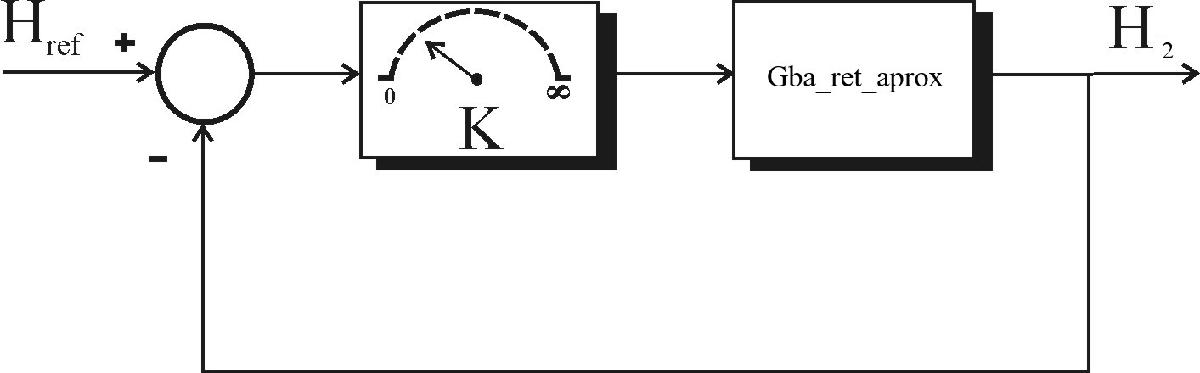

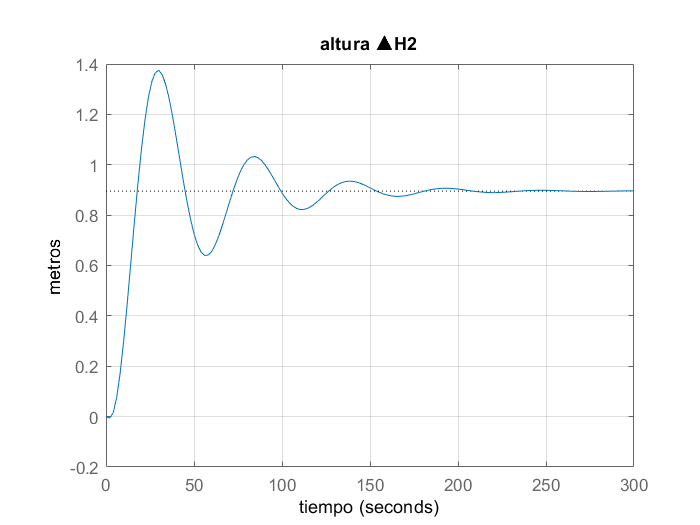

figure  % nueva figura
 step(feedback(0.7*Gba_ret_aprox,1)) % respuesta con K ajustable (usar slider de 0 a 2, intervalo 0.1)
grid                % insertar rejilla
xlabel('tiempo')    % insertar texto en eje X
ylabel('metros')    % insertar texto en eje Y
title('altura ▲H2') % insertar título 

Análisis ajustando la *Kcritica*

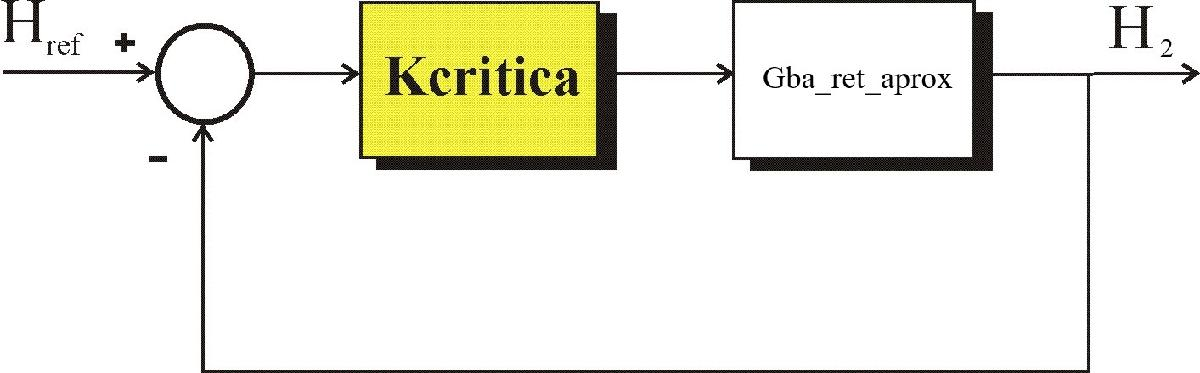

Posición de los polos usando [rlocus](https://es.mathworks.com/help/control/ref/rlocus.html)  (*polos_bc*)

polos_bc=rlocus(Gba_ret_aprox,Kcritica_ret)  % Con rlocus obtención nuevas posiciones de los polos en bucle cerrado

polos_bc =   -0.8794 + 0.0000i
  -0.0000 + 0.1781i
  -0.0000 - 0.1781i


**CONCLUSIÓN:** el sistema está en el límite de la estabilidad con los polos complejos situados sobre el eje imaginario

# **Errores**

Sistema realimentado SIN RETARDO

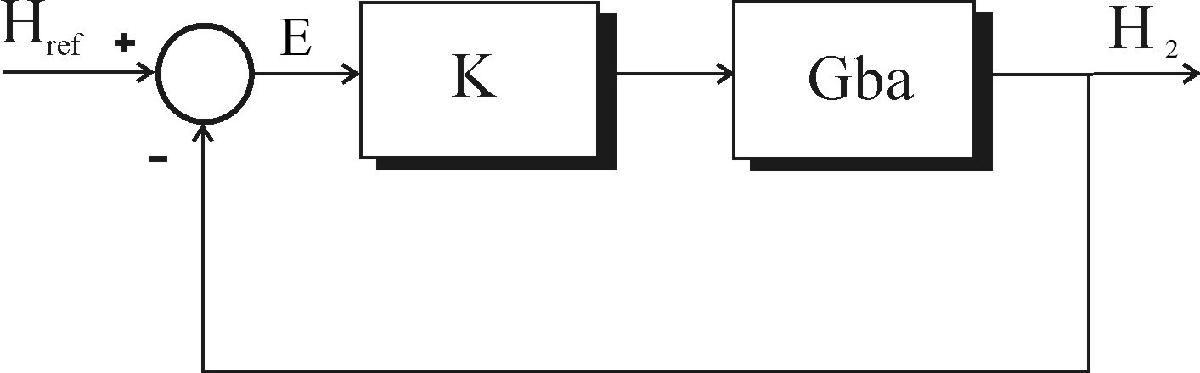

Error de posición      $e_p =\frac{1}{1+K_p }$     siendo $K_p =\underset{s\longrightarrow 0}{\lim \;} G\left(s\right)$

Gba % mostrar Gba=▲H2/▲Qe1


Gba =
 
  From input "Qe" to output "H2":
         0.018475
  -----------------------
  (s+0.04804) (s+0.03141)
 
Continuous-time zero/pole/gain model.



Kp=dcgain(Gba)  % obtención de Kp (ganancia estática de Gba)

Kp = 12.2440

ep=1/(1+Kp)  % fórmula del error de posición

ep = 0.0755

**RECUERDA:** la función [dcgain](https://es.mathworks.com/help/control/ref/dcgain.html) calcula la ganancia estática de un sistema y que es el valor del Kp anterior

Respuesta ante entrada escalón unitario

K=1;  % seguimos considerando K=1
Gbc=feedback(K*Gba,1)  % función de transferencia Gbc del sistema realimentado


Gbc =
 
  From input "Qe" to output:
           0.018475
  --------------------------
  (s^2 + 0.07945s + 0.01998)
 
Continuous-time zero/pole/gain model.



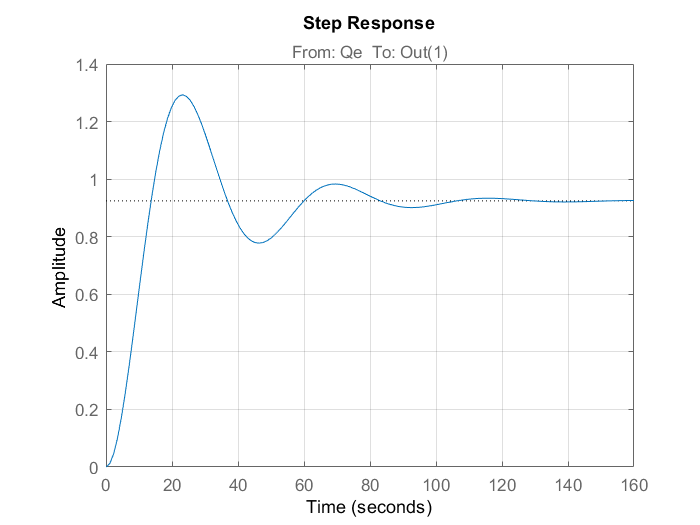

step(Gbc)  % respuesta ante entrada escalón
grid

**NOTA:** con la respuesta en bucle cerrado el cálculo del error se simplifica $\to$ $e_p =1-H_{2\infty } =1-\textrm{dcgain}\left(\textrm{Gbc}\right)$

Evolución del error de posición

- Obteniendo la función de transferencia E/Href:     $\begin{array}{l}
E=H_{\textrm{ref}} -H_2 \;\\
G_{\textrm{bc}} =\frac{H_2 }{H_{\textrm{ref}} }\;
\end{array}$  $\Longrightarrow \;\;\frac{E}{H_{\textrm{ref}} }=\left(1-G_{\textrm{bc}} \right)$

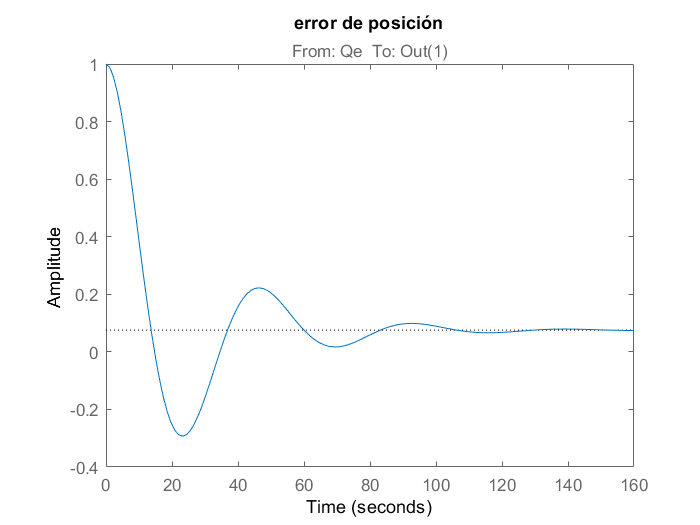

step(1-Gbc)  % error ante entrada escalón
title('error de posición')  % insertar título

- Reorganizando el diagrama de bloques:

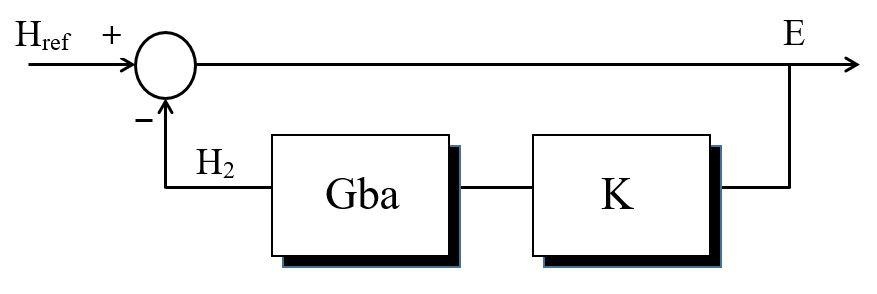

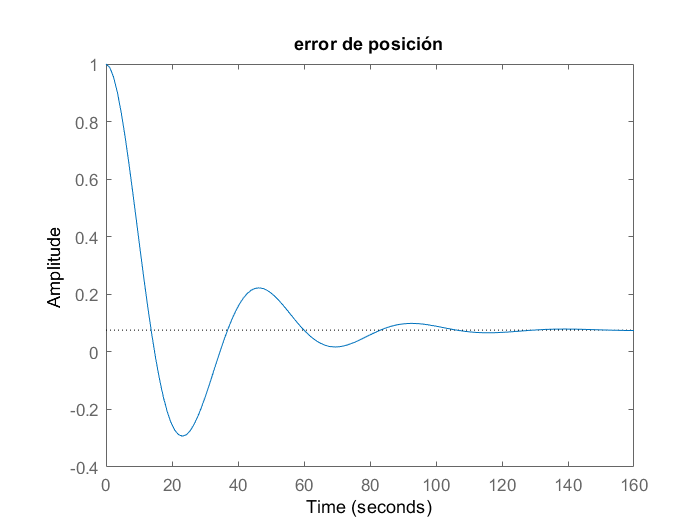

 step(feedback(1,K*Gba)) % error ante entrada escalón
title('error de posición')  % insertar título

Error de velocidad     $e_v =\frac{1}{K_v }$     siendo $K_v =\underset{s\longrightarrow 0}{\lim \;} s\;G\left(s\right)$

 s=tf('s') % declaración de 's' como función de transferencia


s =
 
  s
 
Continuous-time transfer function.



 Kv=dcgain(s*Gba) % cálculo de Kv con dcgain y multiplicando por s

Kv = 0

ev=1/Kv  % fórmula del error de velocidad

ev = Inf

**RECUERDA:** el tipo de sistema, en este ejemplo 0, ya nos dice que el error de velocidad es infinito.

Respuesta ante rampa unitaria

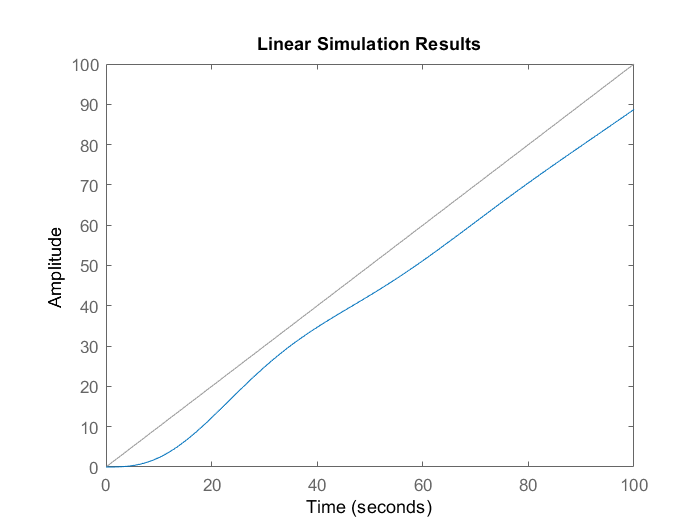

t=0:0.1:100;      % vector tiempo de 0 a 100" (intervalo de 0.1)
rampa=t;          % vector amplitud de la rampa
lsim(Gbc,rampa,t)  % respuesta

**RECUERDA:** la función [lsim](https://es.mathworks.com/help/control/ref/lsim.html) calcula la respuesta de un sistema ante cualquier señal de entrada

# **Reguladores**

##  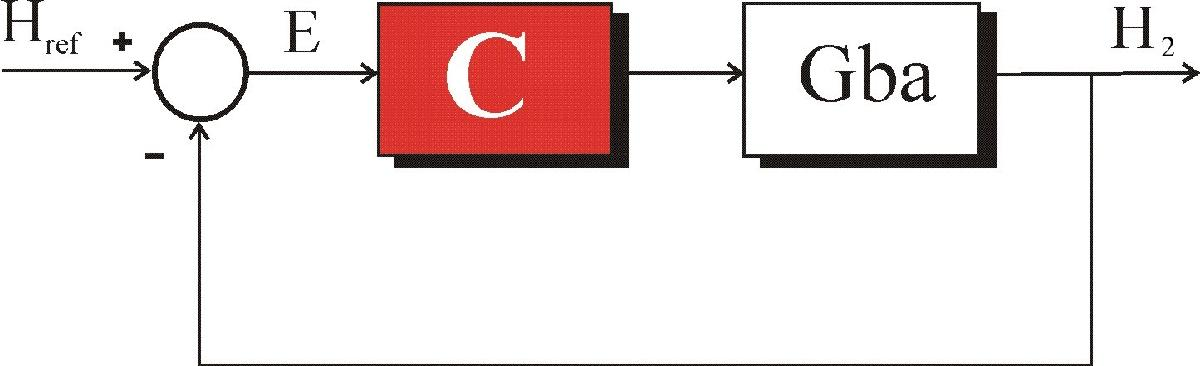

## PID(F) formato paralelo        PID(F) formato estándar        PID(F) formato zpk


$$C\left(s\right)=K_p +\frac{K_i }{s}+\frac{K_d \;s}{T_f \;s+1}$$
                           
$$C\left(s\right)=K_p \;\left\lbrack 1+\frac{1}{T_i \;s}+\frac{T_d \;s}{\left(T_d /N\right)\;s+1}\right\rbrack$$
            
$$C\left(s\right)=K\frac{\left(s+a\right)\left(s+b\right)}{s\;\left(s+c\right)}$$


Declaración con función [pid](https://es.mathworks.com/help/control/ref/pid.html)                        Declaración con función [pidstd](https://es.mathworks.com/help/control/ref/pidstd.html)                      Declaración con función [zpk](https://es.mathworks.com/help/control/ref/zpk.html)

PI paralelo  (*c1*)       $\;C\left(s\right)=K_p +\frac{K_i }{s}$

Kp=0.178; Ki=0.0036;  % Kp ganancia proporcional, Ki ganancia integral
c1=pid(Kp,Ki)  % declaración de c1         


c1 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.178, Ki = 0.0036
 
Continuous-time PI controller in parallel form.



Cambio a formato zpk  (*c1zp*)      $C\left(s\right)=K\frac{\left(s+a\right)}{s}$

c1zp=zpk(c1)  % 1 polo, 1 cero y K


c1zp =
 
  0.178 (s+0.02022)
  -----------------
          s
 
Continuous-time zero/pole/gain model.



PI estándar  (*c2*)      $C\left(s\right)=K_p \;\left\lbrack 1+\frac{1}{T_i \;s}\right\rbrack$

Kp=0.178; Ti=49.4;  % Kp ganancia proporcional, Ti tiempo acción integral
c2=pidstd(Kp,Ti)  % declaración de c2


c2 =
 
             1      1 
  Kp * (1 + ---- * ---)
             Ti     s 

  with Kp = 0.178, Ti = 49.4
 
Continuous-time PI controller in standard form



Cambio a formato zpk  (*c2zp*)      $C\left(s\right)=K\frac{\left(s+a\right)}{s}$

c2zp=zpk(c2)  % 1 polo, 1 cero y K


c2zp =
 
  0.178 (s+0.02024)
  -----------------
          s
 
Continuous-time zero/pole/gain model.



PID paralelo  (*c3*)       $\;C\left(s\right)=K_p +\frac{K_i }{s}+K_d \;s$

Kp=0.922; Ki=0.0272; Kd=7.27;  % Kp ganancia proporcional, Ki ganancia integral, Kd ganancia derivativa
c3=pid(Kp,Ki,Kd)  % declaración de c3         


c3 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.922, Ki = 0.0272, Kd = 7.27
 
Continuous-time PID controller in parallel form.



Cambio a formato zpk  (*c3zp*)       $C\left(s\right)=K\frac{\left(s+a\right)\left(s+b\right)}{s}$

c3zp=zpk(c3)  % 1 polo, 2 ceros y K


c3zp =
 
  7.27 (s+0.08013) (s+0.04669)
  ----------------------------
               s
 
Continuous-time zero/pole/gain model.



**NOTA**: observa es un sistema físicamente irrealizable $\to$ más ceros que polos

PID(F) estándar  (*c4*)      $C\left(s\right)=K_p \;\left\lbrack 1+\frac{1}{T_i \;s}+\frac{T_d \;s}{\left(T_d /N\right)\;s+1}\right\rbrack$

Kp=0.229; Ti=43.4; Td=10;  % Kp ganancia proporcional, Ti tiempo acción integral, Td tiempo acción derivativa
N=59.1;                    % N constante del filtro
c4=pidstd(Kp,Ti,Td,N)  % declaración de c4


c4 =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = 0.229, Ti = 43.4, Td = 10, N = 59.1
 
Continuous-time PIDF controller in standard form



Cambio a formato zpk  (*c4zp*)       $C\left(s\right)=K\frac{\left(s+a\right)\left(s+b\right)}{s\;\left(s+c\right)}$

c4zp=zpk(c4)  % 2 polos, 2 ceros y K


c4zp =
 
  13.763 (s+0.06242) (s+0.0363)
  -----------------------------
           s (s+5.91)
 
Continuous-time zero/pole/gain model.



**NOTA**: observa es un sistema físicamente realizable $\to$ igual número de polos y ceros

**Conversión de formatos****:**

*c3* de paralelo a estándar  (*c3std*)

c3std=pidstd(c3)  % en función de Kp, Ti y Td                    


c3std =
 
             1      1          
  Kp * (1 + ---- * --- + Td * s)
             Ti     s          

  with Kp = 0.922, Ti = 33.9, Td = 7.89
 
Continuous-time PID controller in standard form



*c4* de estándar a paralelo  (*c4par*)

c4par=pid(c4)  % en función de Kp, Ki, Kd y Tf


c4par =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 0.229, Ki = 0.00528, Kd = 2.29, Tf = 0.169
 
Continuous-time PIDF controller in parallel form.



**Comparativa funcionamiento entre reguladores**

sin regulador

step(feedback(Gba,1))  % respuesta al escalón sin regulador

con *c1*

hold  % mantener resultado gráfico anterior

Current plot held


 step(feedback(c1*Gba,1)) % respuesta con regulador c1

con *c2*

step(feedback(c2*Gba,1))  % respuesta con regulador c2

**NOTA:** c1 y c2 son el mismo regulador pero con distinto formato

con *c3*

step(feedback(c3*Gba,1))  % respuesta con regulador c3

con *c4*

step(feedback(c4*Gba,1))  % respuesta con regulador c4

Personalizar la figura

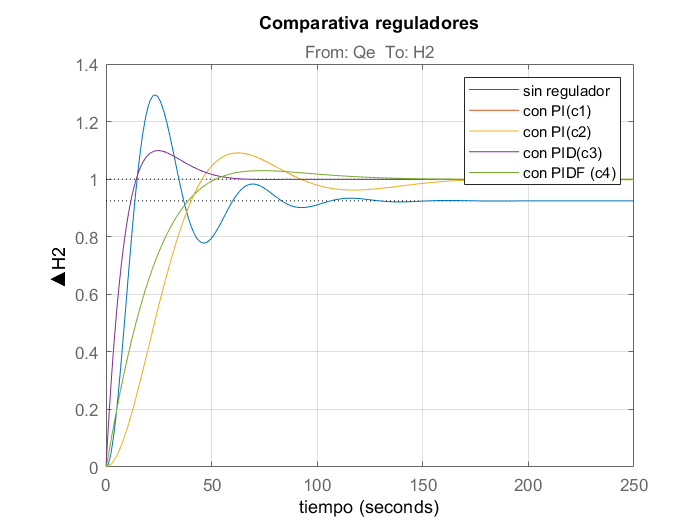

title('Comparativa reguladores') % insertar título
grid                             % insertar rejilla
xlabel('tiempo')                 % insertar texto en eje X
ylabel('▲H2')                    % insertar texto en eje Y
legend('sin regulador','con PI(c1)','con PI(c2)','con PID(c3)','con PIDF (c4)')  % insertar leyenda

**Análisis ante perturbación de entrada**

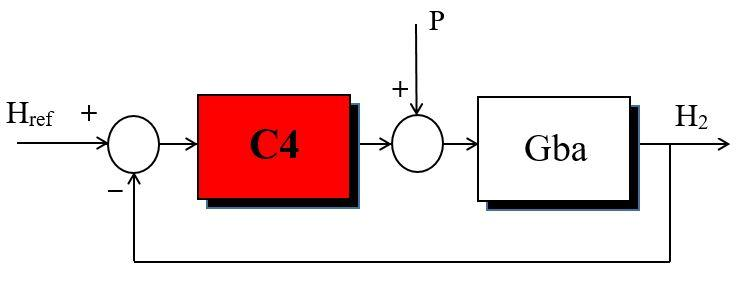

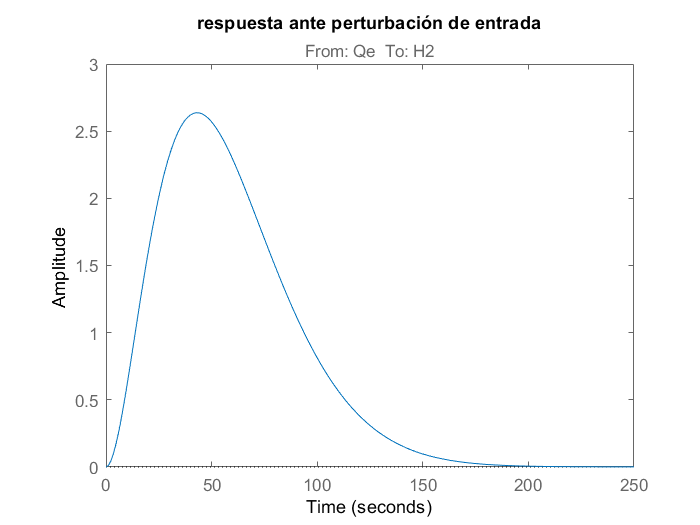

figure  % nueva figura
step(feedback(Gba,c4))  % respuesta ante escalón en perturbación
title('respuesta ante perturbación de entrada') % insertar título

Continuar con:

- **pidTuner**: herramienta para el ajuste de reguladores PID

- **Control System Designer:** herramienta para el análisis y diseño de los sistemas de control

- **Simulink** (ejecutar *DosDepositos_EPB_con_PID.slx*)

Para acceder a los vídeos de la práctica 1 [**clic aquí**](https://edpuzzle.com/join/pavejji)